# Create simulink Enviroment

% Define the Simulink model name
mdl = 'TargetPointTrackingRobotEnv';

% Open the Simulink model
open_system(mdl);

%define init condition
x0  = -10;
y0  = 0;
theta0 = 0;

%define sample time & stop time
Ts = 0.4; 
Tf = 30;    

% Define the observation space(3D vector)
obsInfo = rlNumericSpec([7 1]);

% Define action space (2D vector)
lForceMin = -1.0;    % Minimum left force
lForceMax = 1.0;    % Maximum left force

rForceMin = -1;   % Minimum right force
rForceMax = 1;   % Maximum right force

actInfo = rlNumericSpec([2 1], ...
    'LowerLimit', [lForceMin; rForceMin], ...
    'UpperLimit', [lForceMax; rForceMax]);

% Specify the path to the RL Agent block within the Simulink model
agent = [mdl '/RL Agent'];

% Create the reinforcement learning environment 
env = rlSimulinkEnv(mdl, agent, obsInfo, actInfo);

% Assign a custom reset function to the environment
env.ResetFcn = @(in)TargetPointTrackingRobotResetFcn(in);

% fix random seed
rng(0);

# Create DDPG Agent

%define actor net
actNet = [ 
    featureInputLayer(obsInfo.Dimension(1))
    fullyConnectedLayer(128)
    reluLayer
    fullyConnectedLayer(128)
    reluLayer
    fullyConnectedLayer(128)
    reluLayer
    fullyConnectedLayer(actInfo.Dimension(1))
    ];
actNet = dlnetwork(actNet);
summary(actNet)


   Initialized: true

   Number of learnables: 34.3k

   Inputs:
      1   'input'   7 features



%create actor 
actor = rlContinuousDeterministicActor(actNet,obsInfo,actInfo)

actor =   rlContinuousDeterministicActor with properties:

    ObservationInfo: [1×1 rl.util.rlNumericSpec]
         ActionInfo: [1×1 rl.util.rlNumericSpec]
      Normalization: "none"
          UseDevice: "cpu"
         Learnables: {8×1 cell}
              State: {0×1 cell}



% Observation path layers
obsPath = [
    featureInputLayer(prod(obsInfo.Dimension))
    fullyConnectedLayer(128)
    reluLayer      
    fullyConnectedLayer(5,Name="obsout")
    ];

% Action path layers
actPath = [
    featureInputLayer(prod(actInfo.Dimension))
    fullyConnectedLayer(128)
    reluLayer
    fullyConnectedLayer(7,Name="actout")
    ];

% Common path to output layers
% Concatenate two layers along dimension one.
comPath = [
    concatenationLayer(1,2,Name="cct")
    fullyConnectedLayer(128)
    reluLayer    
    fullyConnectedLayer(1, Name="output")
    ];
%assmbly critic net
criNet = dlnetwork;
criNet = addLayers(criNet,obsPath);
criNet = addLayers(criNet,actPath); 
criNet = addLayers(criNet,comPath);

%connect layer
criNet = connectLayers(criNet,"obsout","cct/in1");
criNet = connectLayers(criNet,"actout","cct/in2");

%init critic net and display it
criNet = initialize(criNet);
summary(criNet)


   Initialized: true

   Number of learnables: 4.7k

   Inputs:
      1   'input'     7 features
      2   'input_1'   2 features




%create critic
critic = rlQValueFunction(criNet,obsInfo,actInfo)

critic =   rlQValueFunction with properties:

    ObservationInfo: [1×1 rl.util.rlNumericSpec]
         ActionInfo: [1×1 rl.util.rlNumericSpec]
      Normalization: ["none"    "none"]
          UseDevice: "cpu"
         Learnables: {12×1 cell}
              State: {0×1 cell}



%define DDPG agnet
criticOptions = rlOptimizerOptions( ...
    LearnRate=1e-03, ...
    GradientThreshold=5);

actorOptions = rlOptimizerOptions( ...
    LearnRate=1e-03, ...
    GradientThreshold=5);

agentOptions = rlDDPGAgentOptions(...
    SampleTime=Ts,...
    ActorOptimizerOptions=actorOptions,...
    DiscountFactor= 0.995,...
    CriticOptimizerOptions=criticOptions,...
    ExperienceBufferLength=1e6 ,...
    TargetSmoothFactor=1e-3,...
    MiniBatchSize=512,...
    MaxMiniBatchPerEpoch=50);

% Gaussian noise
agentOptions.NoiseOptions.MeanAttractionConstant = 1/Ts;
agentOptions.NoiseOptions.StandardDeviation = 1e-1;
agentOptions.NoiseOptions.StandardDeviationMin = 1e-2;
agentOptions.NoiseOptions.StandardDeviationDecayRate = 1e-6;
agentOptions.NoiseOptions.VarianceDecayRate = 1e-5;
agent = rlDDPGAgent(actor,critic,agentOptions);

# Training

%define training option
maxepisodes = 20000;
maxsteps = ceil(Tf/Ts);
trainingOptions = rlTrainingOptions(...
    MaxEpisodes=maxepisodes,...
    MaxStepsPerEpisode=maxsteps,...
    StopOnError="on",...
    Verbose=false,...
    Plots="training-progress",...
    StopTrainingCriteria="AverageReward",... % Stop training based on average reward
    StopTrainingValue=1000,...
    SaveAgentCriteria= "EpisodeReward", ... % Save agent based on episode reward
    SaveAgentValue=500, ...
    ScoreAveragingWindowLength=10);            

% agent evaluator
evl = rlEvaluator(EvaluationFrequency=50,NumEpisodes=5);

doTraining = false

doTraining = logical
   0


if doTraining
    trainingStats = train(agent,env,trainingOptions,Evaluator=evl);
end

# Simulation 

data = struct with fields:
         saved_agent: [1×1 rl.agent.rlDDPGAgent]
    savedAgentResult: [1×1 rl.train.result.rlTrainingResult]


data = struct with fields:
         saved_agent: [1×1 rl.agent.rlDDPGAgent]
    savedAgentResult: [1×1 rl.train.result.rlTrainingResult]


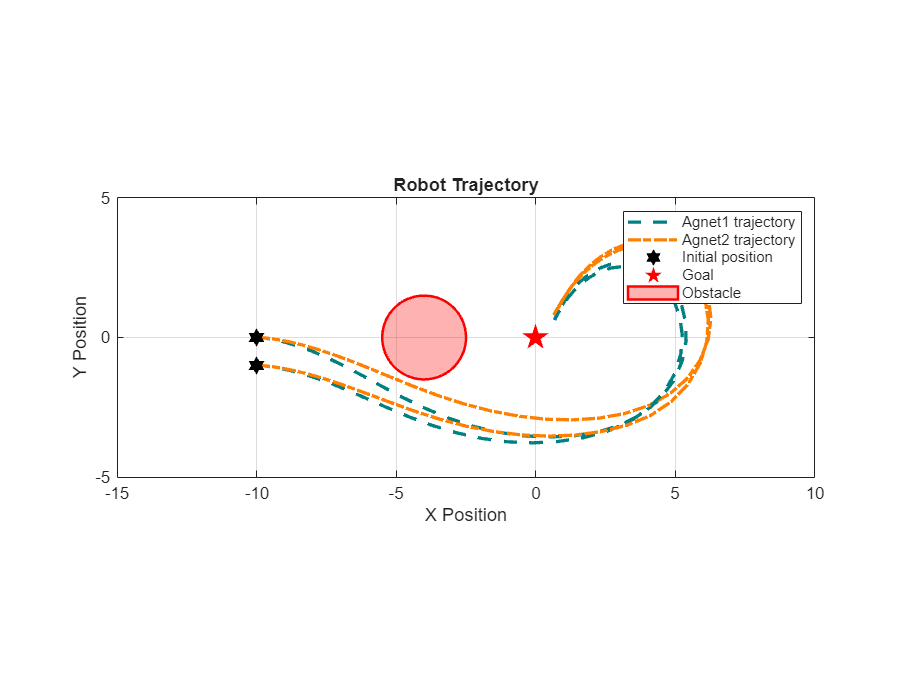

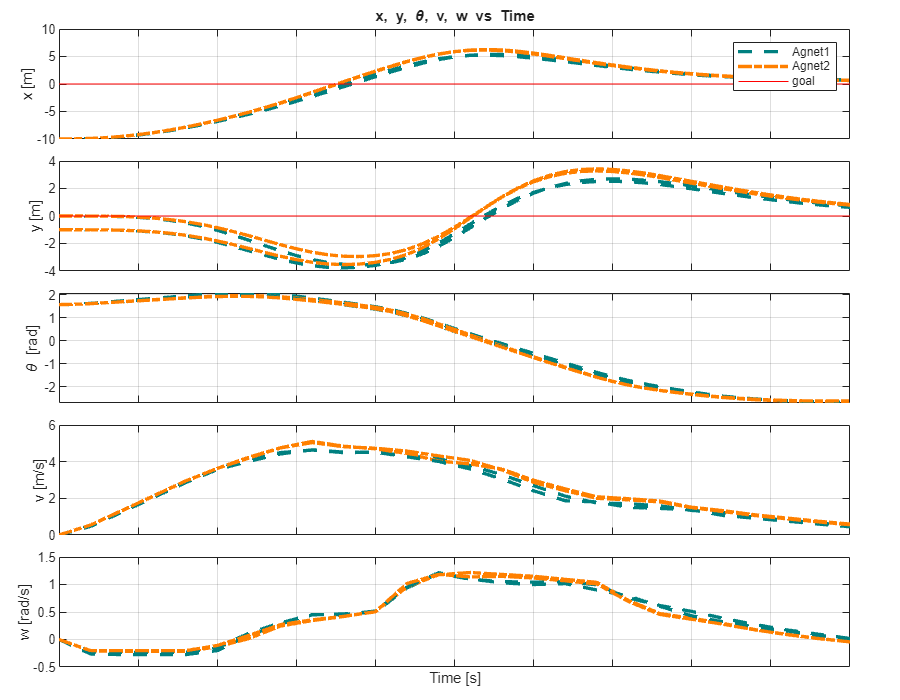

if ~doTraining  % If training is finished, then run simulation and plot
     % Run the simulation with the trained agent

     x0_1 = -10;
     y0_1 = 0;
     x0 = x0_1;
     y0 = y0_1;

    data = load("C:\Users\ex\Dropbox\Junquan Wu\ME I9900 THESIS Research\Matlab Code\RL_Project_Parctise\Target_Tracking_dynamic_model - obstacle\Matlab_code\savedAgents\Agent10720.mat")
    agent1 = data.saved_agent;
 
    agent = agent1;
    simOut = sim(mdl);    
    simout = simOut.get('simout'); 

    t1 = simout.time;                          % Time vector
    simOutdata1 = simout.signals.values;       % Nx5 matrix: [x, y, theta, v, w]
    x1 = simOutdata1(:,1);    
    y1 = simOutdata1(:,2);     
    warp_theta1 = simOutdata1(:,3);    
    theta1 = unwrap(warp_theta1);       % make it continuous
    v1 = simOutdata1(:,4);    
    w1 = simOutdata1(:,5);

    % Run the simulation with the second trained agent
    data = load("C:\Users\ex\Dropbox\Junquan Wu\ME I9900 THESIS Research\Matlab Code\RL_Project_Parctise\Target_Tracking_dynamic_model - obstacle\Matlab_code\savedAgents\Agent10913.mat")
    agent2 = data.saved_agent;

    agent = agent2;
    simOut = sim(mdl);    
    simout = simOut.get('simout'); 
    t2 = simout.time;                          % Time vector
    simOutdata2 = simout.signals.values;       % Nx5 matrix: [x, y, theta, v, w]
    x2 = simOutdata2(:,1);    
    y2 = simOutdata2(:,2);     
    warp_theta2 = simOutdata2(:,3);    
    theta2 = unwrap(warp_theta2);       % make it continuous  
    v2 = simOutdata2(:,4);    
    w2 = simOutdata2(:,5);
    

     % Run the simulation with difference initial position

     x0_2 = -10;
     y0_2 = -1;
     x0 = x0_2;
     y0 = y0_2;

    agent = agent1;
    simOut = sim(mdl);    
    simout = simOut.get('simout'); 

    t1_2 = simout.time;                          % Time vector
    simOutdata1_2 = simout.signals.values;       % Nx5 matrix: [x, y, theta, v, w]
    x1_2 = simOutdata1_2(:,1);    
    y1_2 = simOutdata1_2(:,2);     
    warp_theta1_2 = simOutdata1_2(:,3);    
    theta1_2 = unwrap(warp_theta1_2);       % make it continuous
    v1_2 = simOutdata1_2(:,4);    
    w1_2 = simOutdata1_2(:,5);


    agent = agent2
    simOut = sim(mdl);    
    simout = simOut.get('simout'); 
    t2_2 = simout.time;                          % Time vector
    simOutdata2_2 = simout.signals.values;       % Nx5 matrix: [x, y, theta, v, w]
    x2_2 = simOutdata2_2(:,1);    
    y2_2 = simOutdata2_2(:,2);     
    warp_theta2_2 = simOutdata2_2(:,3);    
    theta2_2 = unwrap(warp_theta2_2);       % make it continuous  
    v2_2 = simOutdata2_2(:,4);    
    w2_2 = simOutdata2_2(:,5);

    % Robot trajectory graph
    figure('Units','pixels','Position',[100 100 720 560]);
    plot(x1, y1, '--', 'color', [0,0.5,0.5], 'LineWidth',2, 'DisplayName', 'Agnet1 trajectory');            
    hold on;
    plot(x2, y2, '-.', 'color', [1,0.5,0], 'LineWidth',2, 'DisplayName', 'Agnet2 trajectory'); 
    plot(x1_2, y1_2, '--', 'color', [0,0.5,0.5], 'LineWidth',2,'HandleVisibility', 'off');        
    plot(x2_2, y2_2, '-.', 'color', [1,0.5,0], 'LineWidth',2,'HandleVisibility', 'off');        
    % initial position (open blue circle)
    plot(x0_1, y0_1, 'h', 'MarkerSize', 10, 'MarkerFaceColor', 'k', 'MarkerEdgeColor','k', 'DisplayName', 'Initial position');
    % second initial position (open blue circle)
    plot(x0_2, y0_2, 'h', 'MarkerSize', 10, 'MarkerFaceColor', 'k', 'MarkerEdgeColor','k','HandleVisibility', 'off');        
    % goal at origin (red star)
    plot(0, 0, 'p', 'MarkerSize', 15, 'MarkerFaceColor', 'r','MarkerEdgeColor', 'r', 'DisplayName', 'Goal');
    
    % Obstacle parameters
    obstacle_center = [-4, 0];
    obstacle_radius = 1.5;

    % Generate circle points
    theta = linspace(0, 2*pi, 200);
    x = obstacle_center(1) + obstacle_radius * cos(theta);
    y = obstacle_center(2) + obstacle_radius * sin(theta);

    % Plot obstacle
    fill(x, y, 'r', 'FaceAlpha', 0.3, 'EdgeColor', 'r', 'LineWidth', 1.5,'DisplayName', 'Obstacle');% Red filled circle
    % plot(obstacle_center(1), obstacle_center(2), 'rx', 'MarkerSize', 8, 'LineWidth', 1.8,'HandleVisibility', 'off');     % Mark center

    hold off;
    xlabel('X Position');
    ylabel('Y Position');
    title('Robot Trajectory');
    legend('show','Location','northeast');
    axis equal; 
    grid on;
    xlim([-15 10])
    ylim([-5 5])

    % graph for all 5 variables vs time
    figure('Units','pixels','Position',[100 100 720 560]);
    tiledlayout(5,1,'TileSpacing','compact','Padding','compact');
    % x vs t graph
    ax1 = nexttile; plot(t1, x1,'--', 'color', [0,0.5,0.5],'LineWidth',2,'DisplayName','Agnet1'); grid on; ylabel('x [m]');  title('x, y, \theta, v, w vs Time');
    hold on;plot(t2, x2,'-.', 'color', [1,0.5,0],'LineWidth',2,'DisplayName','Agnet2');
    plot(t1_2, x1_2,'--', 'color', [0,0.5,0.5],'LineWidth',2,'HandleVisibility', 'off');
    plot(t2_2, x2_2,'-.', 'color', [1,0.5,0],'LineWidth',2,'HandleVisibility', 'off');
    plot(t1, 0*ones(size(t1)), 'k-', 'Color','r','DisplayName', 'goal'); hold off;legend(); set(ax1,'XTickLabel',[]); 

    % y vs t graph
    ax2 = nexttile; plot(t1, y1,'--', 'color', [0,0.5,0.5],'LineWidth',2,'DisplayName','Agnet1'); grid on; ylabel('y [m]');  
    hold on; plot(t2, y2,'-.', 'color', [1,0.5,0],'LineWidth',2,'DisplayName','');
    plot(t1_2, y1_2,'--', 'color', [0,0.5,0.5],'LineWidth',2,'HandleVisibility', 'off');
    plot(t2_2, y2_2,'-.', 'color', [1,0.5,0],'LineWidth',2,'HandleVisibility', 'off');
    plot(t1, 0*ones(size(t1)), 'k-', 'Color','r','DisplayName', 'goal'); hold off; set(ax2,'XTickLabel',[]);

    % theta vs t graph
    ax3 = nexttile; plot(t1, theta1,'--', 'color', [0,0.5,0.5],'LineWidth',2); grid on; ylabel('\theta [rad]'); 
    hold on; plot(t2, theta2,'-.', 'color', [1,0.5,0],'LineWidth',2,'DisplayName','Agnet2'); 
    plot(t1_2, theta1_2,'--', 'color', [0,0.5,0.5],'LineWidth',2,'HandleVisibility', 'off');
    plot(t2_2, theta2_2,'-.', 'color', [1,0.5,0],'LineWidth',2,'HandleVisibility', 'off');
    set(ax3,'XTickLabel',[]);

    % v vs t graph
    ax4 = nexttile; plot(t1, v1,'--', 'color', [0,0.5,0.5],'LineWidth',2); grid on; ylabel('v [m/s]');
    hold on; plot(t2, v2,'-.', 'color', [1,0.5,0],'LineWidth',2,'DisplayName','Agnet2');  
    plot(t1_2, v1_2,'--', 'color', [0,0.5,0.5],'LineWidth',2,'HandleVisibility', 'off');
    plot(t2_2, v2_2,'-.', 'color', [1,0.5,0],'LineWidth',2,'HandleVisibility', 'off');
    set(ax4,'XTickLabel',[]);

    % w vs t graph
    ax5 = nexttile; plot(t1, w1,'--', 'color', [0,0.5,0.5],'LineWidth',2); grid on; ylabel('w [rad/s]'); xlabel('Time [s]');
    hold on; plot(t2, w2,'-.', 'color', [1,0.5,0],'LineWidth',2,'DisplayName','Agnet2'); 
    plot(t1_2, w1_2,'--', 'color', [0,0.5,0.5],'LineWidth',2,'HandleVisibility', 'off');
    plot(t2_2, w2_2,'-.', 'color', [1,0.5,0],'LineWidth',2,'HandleVisibility', 'off');
    set(ax5,'XTickLabel',[]);

    linkaxes([ax1 ax2 ax3 ax4 ax5],'x');
end